# Turotial: EPI Distortion Correction

# Part 1: Static Distortion Correction = using a single field map

## Computational Steps Overview:

- Defining inputs

- Calculating Voxel Shift Map from GEFM phase data

- Coregistering Voxel Shift Map to EPI

- Unwarping 

- Quality assurance

## Step 1 - Defining inputs

Let's have a look at the available data

**Field map data:** magnitude and phase difference from dual-echo GRE scan (GEFM)

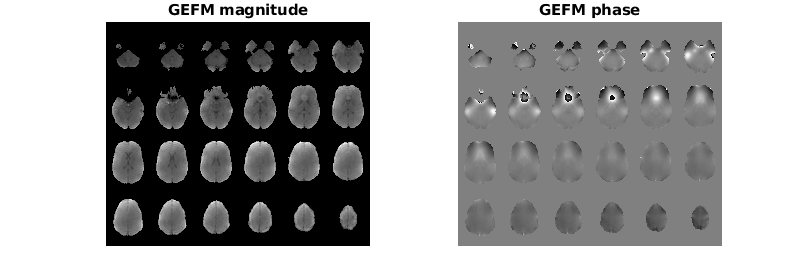

working_dir = '/home/bdymerska/Documents/data/7T/2022/20221130.M700466_FIL/tutorial/data_copy2' ;

cd(working_dir)
GEFM_mag = nifti('GEFM_mag.nii').dat(:,:,:) ;
GEFM_phdiff = nifti('GEFM_ph.nii').dat(:,:,:) ;

figure('Position', [0 0 1200 400]);
subplot 121 
montage(mat2gray(permute(GEFM_mag(:,25:48,:),[1 3 4 2])))
title('GEFM magnitude')
subplot 122 
montage(mat2gray(permute(GEFM_phdiff(:,25:48,:),[1 3 4 2])))
title('GEFM phase')

**EPI data:** multi-volume magnitude data from EPI run:

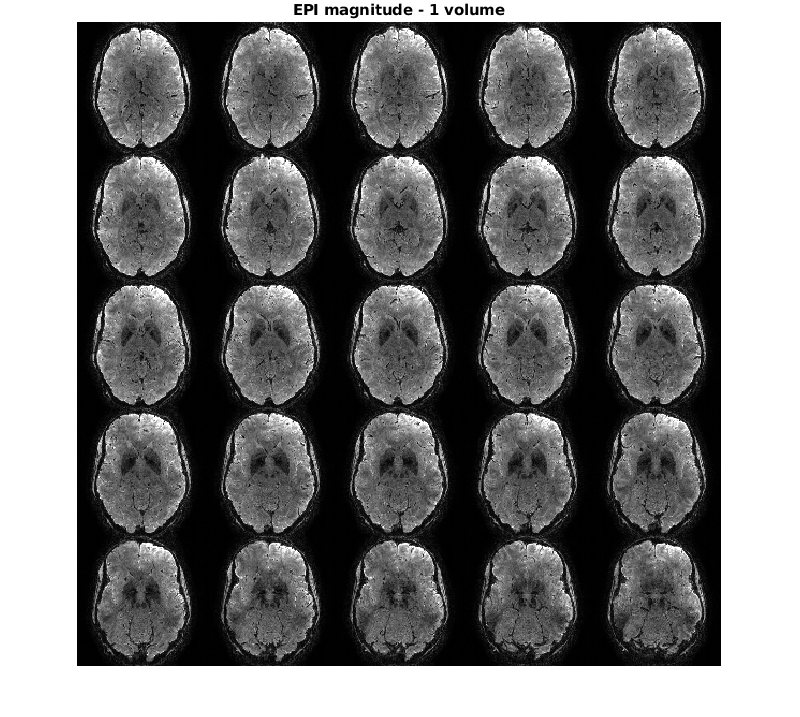

vol_nr = 50 ;
EPI = nifti(fullfile(working_dir,'EPI','mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
figure('Position', [0 0 1000 600]); 
montage(mat2gray(permute(EPI(:,:,26:end-38),[2 1 4 3]),[0 1000]));
title('EPI magnitude - 1 volume');

## Step 2 - Calculating Voxel Shift Map from GEFM phase data

We will do:

    A. Phase Unwrapping 

    B. Field Map Calculation

    C. Field Map Extrapolation

    D. Voxel Shift Map Calculation

### A. Phase Unwrapping

There is many phase unwrapping algorithms. Examples: PRELUDE (FSL) [1], BEST PATH [2], or ROMEO [3].

Some of them recquire that the phase is in $\left\lbrack 0\;2\pi \right)$range, our GEFM phase has the following range:

[GEFM_ph_min,GEFM_ph_max]  = bounds( GEFM_phdiff(:) , "all" )

GEFM_ph_min = -4096

GEFM_ph_max = 4092

We can rescale the GEFM phase data (if we need to) using:

GEFM_phdiff = 2*pi*(GEFM_phdiff - GEFM_ph_min)/(GEFM_ph_max-GEFM_ph_min) ;
[GEFM_ph_min,GEFM_ph_max]  = bounds( GEFM_phdiff(:) , "all" )

GEFM_ph_min = 0

GEFM_ph_max = 6.2832

But we will use ROMEO phase unwrapping which does the phase data rescaling for us:

system('romeo -p GEFM_ph.nii -m GEFM_mag.nii -o GEFM_ph_unwr.nii');

Let's have a look if the data were properly unwrapped:

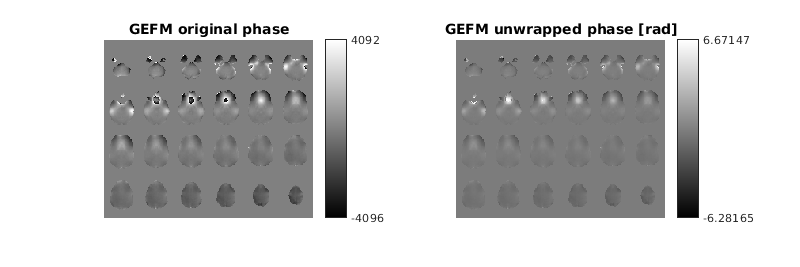

GEFM_phdiff = nifti('GEFM_ph.nii').dat(:,:,:) ;
GEFM_phdiff_unwr = nifti('GEFM_ph_unwr.nii').dat(:,:,:) ;

figure('Position', [0 0 900 300]); 
subplot 121 
montage(mat2gray(permute(GEFM_phdiff(:,25:48,:),[1 3 4 2])))
[GEFM_ph_min,GEFM_ph_max]  = bounds( GEFM_phdiff(:) , "all" );
colorbar('Ticks',[0 1],'TickLabels',{GEFM_ph_min,GEFM_ph_max});
title('GEFM original phase')
subplot 122 
montage(mat2gray(permute(GEFM_phdiff_unwr(:,25:48,:),[1 3 4 2])))
[GEFM_ph_min,GEFM_ph_max]  = bounds( GEFM_phdiff_unwr(:) , "all" );
colorbar('Ticks',[0 1],'TickLabels',{GEFM_ph_min,GEFM_ph_max});
title('GEFM unwrapped phase [rad]');

### B. Field Map Calculation

Above, we unwrapped GEFM phase difference obtaining smooth map of phase variation in radian, $\Delta \theta$. 

We obtain Field Map, $\Delta B_0$,  in Hertz by dividing the phase difference by $2\pi$and echo time difference:


$$\Delta B_0 =\frac{\Delta \theta }{2\pi \Delta \textrm{TE}}\left\lbrack \textrm{Hz}\right\rbrack$$


GEFM_TEdiff = 3.06e-3;  % echo time difference in seconds
GEFM = GEFM_phdiff_unwr/(2*pi*GEFM_TEdiff) ;

Luckily, ROMEO can do this calculation for us by adding "-B" to previous ROMEO call:

system('romeo -p GEFM_ph.nii -m GEFM_mag.nii -o GEFM_ph_unwr.nii -t 3.06 -B');

please mind $\Delta \textrm{TE}$ is in $\left\lbrack \textrm{ms}\right\rbrack$ and output $\Delta B_0$ is in $\left\lbrack \textrm{Hz}\right\rbrack$.

Equivalent in FSL would be (with $\Delta B_0$ is in $\left\lbrack \textrm{rad}\cdot \textrm{Hz}\right\rbrack$) :

%unix('fsl_prepare_fieldmap SIEMENS GEFM_ph.nii GEFM_mag.nii GEFM_FSL_radHz.nii 3.08');

### C. Field Map Extrapolation 

Let's load the Field Map calculated by ROMEO and extrapolate it outside the masked area, so that we can do more accurate distortion correction at the brain bounaries. Smoothn by D.Garcia provides robust extrapolation of 3D data with missing values [4].

GEFM = nifti('B0.nii').dat(:,:,:);
GEFM_extrap = GEFM;
GEFM_extrap(GEFM_extrap==0) = NaN;
GEFM_extrap = smoothn(GEFM_extrap, 1, 'MaxIter',300);

Let's compare Field Map with and without extrapolation.

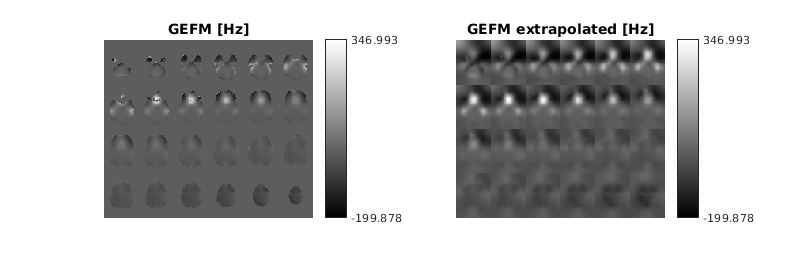

figure('Position', [0 0 900 300]); 
subplot 121 
montage(mat2gray(permute(GEFM(:,25:48,:),[1 3 4 2])))
[GEFM_min,GEFM_max]  = bounds( GEFM(:) , "all" );
colorbar('Ticks',[0 1],'TickLabels',{GEFM_min,GEFM_max});
title('GEFM [Hz]')
subplot 122 
montage(mat2gray(permute(GEFM_extrap(:,25:48,:),[1 3 4 2])))
colorbar('Ticks',[0 1],'TickLabels',{GEFM_min,GEFM_max});
title('GEFM extrapolated [Hz]');

### D. Voxel Shift Map Calculation

We want to know by how much we have to shift a particular voxel in EPI volume with a given signal intensity along the Phase Encoding (PE) direction.

The relationship between Voxel Shift Map (VSM) and a Field Map is as following:


$$\textrm{VSM}=\frac{\Delta B_0 \cdot M_{\textrm{PE}} \cdot t_{\textrm{esp}} }{R}\;\left\lbrack \textrm{voxels}\right\rbrack$$


where:

$M_{\textrm{PE}}$ - Matrix size in PE direction

$t_{\textrm{esp}}$   - Echo spacing time, e.g. for trapezoid gradient form: 1 x flat top time + 2 x ramp up time

$R$     - Acceleration in PE direction

For this sample EPI dataset it will be:

M_PE = 240;
t_esp = (800 +2*210)*1e-6; % in seconds
R = 2*4; % this EPI was acquired with 2 in-plane segments and 4-fold undersampling

VSM = GEFM_extrap*M_PE*t_esp/R ;

createNifti(VSM, 'VSM_SDC.nii', nifti('B0.nii').mat)

## Step 3 - Coregistering Voxel Shift Map to EPI

We will use SPM12 [5] Coregister functionality embedded in the following wrapper:

coreg_GEFM2EPI('EPI/mag/mag_50.nii', 'GEFM_mag.nii', 'VSM_SDC.nii');



------------------------------------------------------------------------
22-May-2023 16:27:24 - Running job #7
------------------------------------------------------------------------
22-May-2023 16:27:24 - Running 'Coregister: Estimate & Reslice'

SPM12: spm_coreg (v7320)                           16:27:24 - 22/05/2023
Completed                               :          16:27:27 - 22/05/2023

SPM12: spm_reslice (v7141)                         16:27:27 - 22/05/2023
Completed                               :          16:27:28 - 22/05/2023
22-May-2023 16:27:28 - Done    'Coregister: Estimate & Reslice'
22-May-2023 16:27:28 - Done



Let's have a look at a volume of EPI and coregisterred VSM next to each other:

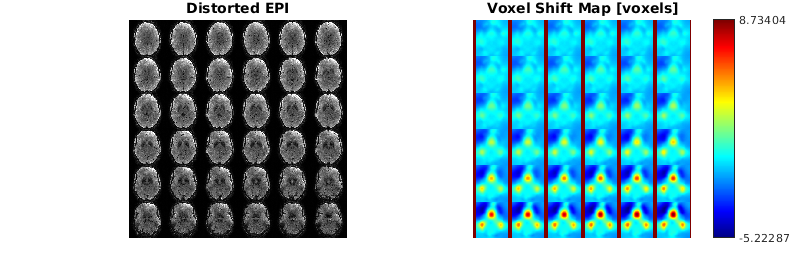

VSM = nifti('coreg2EPI_VSM_SDC.nii').dat(:,:,:);
figure('Position', [0 0 900 300]); 
subplot 121 
montage(mat2gray(permute(EPI(:,:,20:end-33),[2 1 4 3]),[0 1000]))
title('Distorted EPI');
ax2 = subplot(1,2,2) ;
montage(mat2gray(permute(VSM(:,:,20:end-33),[2 1 4 3])))
[VSM_min,VSM_max]  = bounds( VSM(:) , "all" );

ax = gca;
ax.Position(3) = 1.2*ax.Position(3);
colormap(ax2, jet)
colorbar('Ticks',[0 1],'TickLabels',{VSM_min,VSM_max});
title('Voxel Shift Map [voxels]')

## Step 4 - Unwarping 

We will now apply VSM to shift voxel intensities along Phase Encoding direction and apply additional intensity correction:

- VSM values are noninteger, which means we have to interpolate the outcome back to uniform spatial grid. Here, for interpolation we will use spm_sample_vol function from SPM12 [5] and manual warp-field creation.

- Shifting voxel intensities using VSM does not correct for signal intensity changes caused by signal compression and stretching.

- A common method to correct voxel intensities is to multiply local Jacobian determinant of the VSM with the distortion corrected image. The Jacobian determinant reflects the relative local volume change when mapping from the undistorted to distorted spaces.

TP = 50 ; % let's test unwarping on a few of EPI volumes
interp_method = 7 ; % 1 is trilinear, values > 0 are nth order polnomial, values < 0 are nth order sinc ...

[Mx, My, Mz] = size(EPI); % reading matrix size of the EPI
[x,y,z] = ndgrid(1:Mx,1:My,1:Mz); % creating rectangular grid for 3D space

% creating warp field, VSM must be added to the PE-direction - here 2nd dim
F_warp = [x(:) y(:) z(:)]; 
F_warp(:,2) = F_warp(:,2) + reshape(VSM,[Mx*My*Mz,1]);

% Jacobian determinant: We have significant distortionc only in
% PE-direction, so J_field calculation boils down to gradient in PE-direction calculation
VSM_grad = (circshift(VSM,1,2)-circshift(VSM,-1,2))/2 ;
VSM_grad(~isfinite(VSM_grad))=0;
J_field = 1 + VSM_grad ;

mag_SDC = zeros(Mx,My,Mz) ;
for t = 1 : TP

    EPI_file = fullfile('EPI/mag',sprintf('mag_%02.f.nii',t)) ;
    fprintf('Unwarping %s \n', EPI_file)

    EPI_SDC = reshape(spm_sample_vol(spm_vol(EPI_file),...
        F_warp(:,1),F_warp(:,2),F_warp(:,3),interp_method),[Mx,My,Mz]);

    EPI_SDC_file = fullfile('EPI/mag',sprintf('mag_%02.f_sdc.nii',t)) ;
    createNifti(EPI_SDC, EPI_SDC_file, nifti(EPI_file).mat)


    EPI_SDC_jac = EPI_SDC.*J_field ;

    EPI_SDC_file = fullfile('EPI/mag',sprintf('mag_%02.f_sdc_jac.nii',t)) ;
    createNifti(EPI_SDC_jac, EPI_SDC_file, nifti(EPI_file).mat)

end

Unwarping EPI/mag/mag_01.nii 
Unwarping EPI/mag/mag_02.nii 
Unwarping EPI/mag/mag_03.nii 
Unwarping EPI/mag/mag_04.nii 
Unwarping EPI/mag/mag_05.nii 
Unwarping EPI/mag/mag_06.nii 
Unwarping EPI/mag/mag_07.nii 
Unwarping EPI/mag/mag_08.nii 
Unwarping EPI/mag/mag_09.nii 
Unwarping EPI/mag/mag_10.nii 
Unwarping EPI/mag/mag_11.nii 
Unwarping EPI/mag/mag_12.nii 
Unwarping EPI/mag/mag_13.nii 
Unwarping EPI/mag/mag_14.nii 
Unwarping EPI/mag/mag_15.nii 
Unwarping EPI/mag/mag_16.nii 
Unwarping EPI/mag/mag_17.nii 
Unwarping EPI/mag/mag_18.nii 
Unwarping EPI/mag/mag_19.nii 
Unwarping EPI/mag/mag_20.nii 
Unwarping EPI/mag/mag_21.nii 
Unwarping EPI/mag/mag_22.nii 
Unwarping EPI/mag/mag_23.nii 
Unwarping EPI/mag/mag_24.nii 
Unwarping EPI/mag/mag_25.nii 
Unwarping EPI/mag/mag_26.nii 
Unwarping EPI/mag/mag_27.nii 
Unwarping EPI/mag/mag_28.nii 
Unwarping EPI/mag/mag_29.nii 
Unwarping EPI/mag/mag_30.nii 
Unwarping EPI/mag/mag_31.nii 
Unwarping EPI/mag/mag_32.nii 
Unwarping EPI/mag/mag_33.nii 
Unwarping 

## Step 5 - Quality Assurance

Let's first have a look at the difference between original and distortion corrected images:

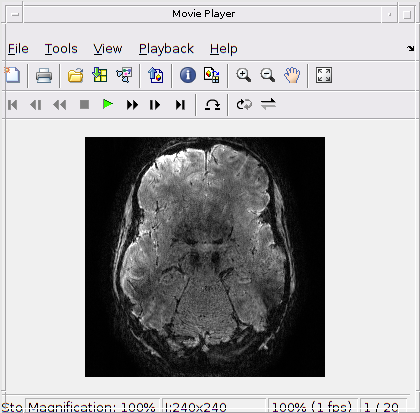

vol_nr = 1 ;
slice = 43 ;

EPI = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
EPI_1vol_SDC = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_sdc.nii',vol_nr))).dat(:,:,:) ;
EPI_1vol_SDC_jac = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_sdc_jac.nii',vol_nr))).dat(:,:,:) ;

EPI_noDC_SDC = cat(3, EPI(:,:,slice), EPI_1vol_SDC(:,:,slice)) ;
EPI_noDC_SDC = repmat(EPI_noDC_SDC, [1 1 10]);
implay(mat2gray(imrotate(EPI_noDC_SDC,-90),[0 1000]), 1)

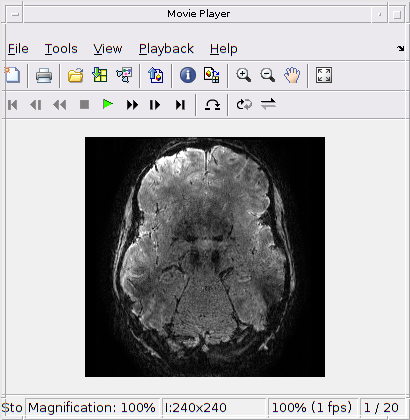

EPI_SDC_SDCjac = cat(3, EPI_1vol_SDC(:,:,slice), EPI_1vol_SDC_jac(:,:,slice)) ;
EPI_SDC_SDCjac = repmat(EPI_SDC_SDCjac, [1 1 10]);
implay(mat2gray(imrotate(EPI_SDC_SDCjac,-90),[0 1000]), 1)

How do we know if we minimized/removed geometric distortions?

Good examples of quality assurance can be found in Ref. [6]:

We can for instance calculate Dice coefficient between Gray Matter (GM) mask from structural reference and EPI.

Let's have a look at MP2RAGE and EPI together:

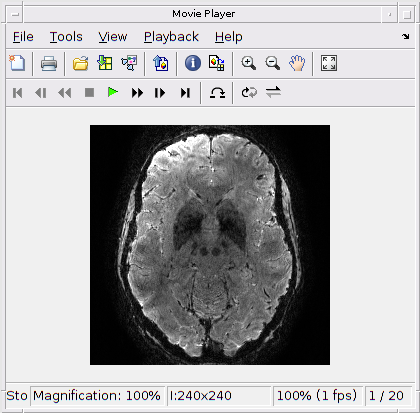

vol_nr = 1 ;
slice = 43 ;

EPI = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f.nii',vol_nr))).dat(:,:,:) ;
MP2RAGE = nifti(fullfile(working_dir, 'coreg2EPI_mp2rage.nii')).dat(:,:,:);
MP2RAGE(~isfinite(MP2RAGE))=0;
EPI_SDC_MP2RAGE = cat(3, mat2gray(EPI(:,:,slice),[0 1000]), mat2gray(MP2RAGE(:,:,slice),[0 4100])) ;
EPI_SDC_MP2RAGE = repmat(EPI_SDC_MP2RAGE, [1 1 10]);
implay(imrotate(EPI_SDC_MP2RAGE,-90), 1)

vol_nr = 1 ;
slice = 43 ;

EPI_1vol_SDC = nifti(fullfile(working_dir,'EPI/mag',sprintf('mag_%02.f_sdc.nii',vol_nr))).dat(:,:,:) ;
MP2RAGE = nifti(fullfile(working_dir, 'coreg2EPI_mp2rage.nii')).dat(:,:,:);
MP2RAGE(~isfinite(MP2RAGE))=0;
EPI_SDC_MP2RAGE = cat(3, mat2gray(EPI_1vol_SDC(:,:,slice),[0 1000]), mat2gray(MP2RAGE(:,:,slice),[0 4100])) ;
EPI_SDC_MP2RAGE = repmat(EPI_SDC_MP2RAGE, [1 1 10]);
implay(imrotate(EPI_SDC_MP2RAGE,-90), 1)

Let's load Gray Matter masks for MP2RAGE and EPIs and calculate Dice Coefficients:

GM_threshold = 0.5 ;
slice = 43 ;
MP2RAGE_GM = nifti(fullfile(working_dir,'coreg2EPI_mp2rage_GM.nii')).dat(:,:,slice);
EPI_GM = nifti(fullfile(working_dir,'EPI/mag','mag_01_GM.nii')).dat(:,:,slice) ;
EPI_SDC_GM = nifti(fullfile(working_dir,'EPI/mag','mag_01_sdc_GM.nii')).dat(:,:,slice) ;
EPI_SDCjac_GM = nifti(fullfile(working_dir,'EPI/mag','mag_01_sdc_jac_GM.nii')).dat(:,:,slice) ;

MP2RAGE_GM = imbinarize(MP2RAGE_GM, GM_threshold);
EPI_GM = imbinarize(EPI_GM, GM_threshold);
EPI_SDC_GM = imbinarize(EPI_SDC_GM, GM_threshold);
EPI_SDCjac_GM = imbinarize(EPI_SDCjac_GM, GM_threshold);

MP2RAGE_EPI_dice = dice(MP2RAGE_GM, EPI_GM)

MP2RAGE_EPI_dice = 0.6494

MP2RAGE_EPI_SDC_dice = dice(MP2RAGE_GM, EPI_SDC_GM)

MP2RAGE_EPI_SDC_dice = 0.6900

MP2RAGE_EPI_SDCjac_dice = dice(MP2RAGE_GM, EPI_SDCjac_GM)

MP2RAGE_EPI_SDCjac_dice = 0.7152

## References:

[1] Jenkinson, Mark. "Fast, automated, N‐dimensional phase‐unwrapping algorithm." *Magnetic Resonance in Medicine: An Official Journal of the International Society for Magnetic Resonance in Medicine* 49.1 (2003): 193-197.

[2] Abdul-Rahman, Hussein S., et al. "Fast and robust three-dimensional best path phase unwrapping algorithm." *Applied optics* 46.26 (2007): 6623-6635.

[3] Dymerska, Barbara, and Eckstein, Korbinian, et al. "Phase unwrapping with a rapid opensource minimum spanning tree algorithm (ROMEO)." *Magnetic resonance in medicine* 85.4 (2021): 2294-2308.

[https://github.com/korbinian90/ROMEO](https://github.com/korbinian90/ROMEO)

[4] [https://uk.mathworks.com/matlabcentral/fileexchange/25634-smoothn](https://uk.mathworks.com/matlabcentral/fileexchange/25634-smoothn)

[5] [https://github.com/spm/](https://github.com/spm/)

[6] Malekian et al, 

[https://github.com/fil-physics/Publication-Code/tree/master/3DEPI-DistortionCorrection](https://github.com/fil-physics/Publication-Code/tree/master/3DEPI-DistortionCorrection)

## Alternative solution using FSL functions:

### Apply calculate and apply GEFM (partially pseudo code):

unix('fsl_prepare_fieldmap SIEMENS GEFM_ph.nii GEFM_mag.nii GEFM_FSL_radHz.nii 3.08');
% unix('epi_reg --epi=<EPI image> --t1=<wholehead T1 image> --t1brain=<brain extracted T1 image> --out=<output name> --fmap=GEFM_radHz --echospacing=<t_esp> --pedir=y-')

For more information please see: [https://fsl.fmrib.ox.ac.uk/fsl/fslwiki/FLIRT/UserGuide](https://fsl.fmrib.ox.ac.uk/fsl/fslwiki/FLIRT/UserGuide)

### Use EPI reverse-polarity approach, i.e. TOPUP (pseudo code):

% unix('topup --imain=EPI_APvol_PAvol.nii --datain=param.txt --config=b02b0.cnf --out=topup_results --fout=topup_field.nii --iout=EPI_APvol_PAvol_topup_unwarped.nii --jacout=jac --rbmout=xfm --dfout=topup_warpfield.nii')
% unix('applytopup --imain=EPI_AP_time_series.nii --topup=topup_results --datain=param.txt --inindex=1 --out=EPI_AP_time_series_topup_unwarped.nii --method=jac'])

For more information please see: [https://fsl.fmrib.ox.ac.uk/fsl/fslwiki/topup](https://fsl.fmrib.ox.ac.uk/fsl/fslwiki/topup)

## Acknowledgements

The Wellcome Centre for Human Neuroimaging is supported by core funding from the Wellcome [203147/Z/16/Z].

Many thanks to Prof. Eleanor Maguire and her student Yan Wu for sharing their 7T MRI data from project funded by a Wellcome Principal Research Fellowship to E. Maguire (grant reference: 210567/Z/18/Z).